m = 26

m = 26

k = 72

k = 72


A = 1 / k

A = 0.0139

T_ = sqrt(m / k)

T_ = 0.6009


t = linspace(0, 15)

t =          0    0.1515    0.3030    0.4545    0.6061    0.7576    0.9091    1.0606    1.2121    1.3636    1.5152    1.6667    1.8182    1.9697    2.1212    2.2727    2.4242    2.5758    2.7273    2.8788    3.0303    3.1818    3.3333    3.4848    3.6364    3.7879    3.9394    4.0909    4.2424    4.3939    4.5455    4.6970    4.8485    5.0000    5.1515    5.3030    5.4545    5.6061    5.7576    5.9091    6.0606    6.2121    6.3636    6.5152    6.6667    6.8182    6.9697    7.1212    7.2727    7.4242



y_ir = (A / T_) * sin(t / T_)

y_ir =          0    0.0058    0.0112    0.0159    0.0196    0.0220    0.0231    0.0227    0.0208    0.0177    0.0134    0.0083    0.0027   -0.0031   -0.0088   -0.0138   -0.0180   -0.0210   -0.0228   -0.0230   -0.0219   -0.0193   -0.0155   -0.0108   -0.0053    0.0005    0.0062    0.0116    0.0162    0.0198    0.0221    0.0231    0.0226    0.0206    0.0174    0.0131    0.0079    0.0022   -0.0036   -0.0092   -0.0142   -0.0183   -0.0212   -0.0228   -0.0230   -0.0217   -0.0190   -0.0152   -0.0103   -0.0049



num_i = [A];
den_i = [T_^2 0 1];
sys_i = tf(num_i, den_i);

y_sr = A - A * cos(t / T_)

y_sr =          0    0.0004    0.0017    0.0038    0.0065    0.0097    0.0131    0.0166    0.0199    0.0228    0.0252    0.0268    0.0277    0.0276    0.0267    0.0250    0.0226    0.0196    0.0163    0.0128    0.0094    0.0062    0.0036    0.0016    0.0004    0.0000    0.0005    0.0019    0.0040    0.0067    0.0099    0.0134    0.0168    0.0201    0.0230    0.0254    0.0269    0.0277    0.0276    0.0266    0.0249    0.0224    0.0194    0.0160    0.0125    0.0091    0.0060    0.0034    0.0015    0.0003


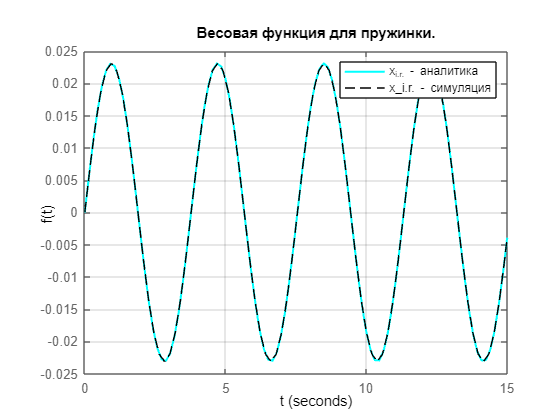


num_s = [A];
den_s = [T_^2 0 1 0];
sys_s = tf(num_s, den_s);


plot(t, y_ir, 'c', LineWidth=1.5)
hold on
impulse(sys_i, 'k--')
legend('x_{i.r.} - аналитика', 'x_{i.r.} - симуляция')
title('Весовая функция для пружинки.')
grid()
ylabel("f(t)")
xlabel('t')
xlim([0 15])
hold off

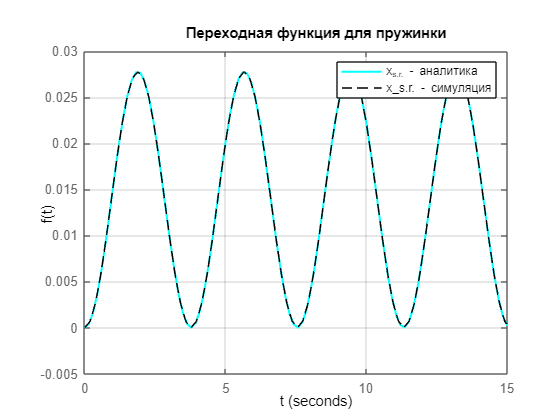




plot(t, y_sr, 'c', LineWidth=1.5)
hold on
impulse(sys_s, 'k--')
legend('x_{s.r.} - аналитика', 'x_{s.r.} - симуляция')
title('Переходная функция для пружинки')
grid()
ylabel("f(t)")
xlabel('t')
xlim([0 15])
hold off



w = linspace(0, 5)

w =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747



ach = abs(1 ./ (k - m * w .* w))

ach =     0.0139    0.0139    0.0139    0.0140    0.0141    0.0142    0.0144    0.0145    0.0148    0.0150    0.0153    0.0156    0.0160    0.0164    0.0169    0.0175    0.0182    0.0189    0.0198    0.0208    0.0220    0.0234    0.0251    0.0271    0.0296    0.0327    0.0368    0.0423    0.0500    0.0616    0.0812    0.1210    0.2446    4.5000    0.2143    0.1082    0.0717    0.0532    0.0421    0.0346    0.0293    0.0253    0.0222    0.0198    0.0177    0.0161    0.0146    0.0134    0.0124    0.0115


phi = -atan2(0, 1 ./ (k - m * w .* w)) * 180 / pi

phi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180  -180


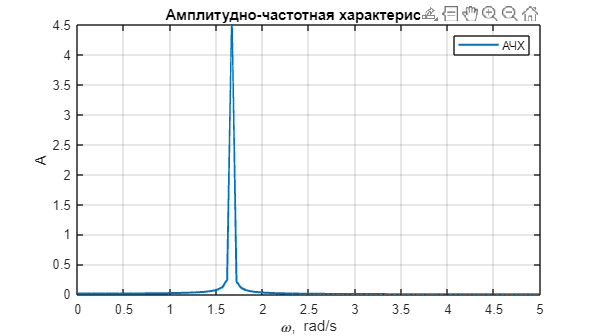


figure('Position', [1000 0 800 450])
plot(w, ach, LineWidth=1.5)

grid("on")
ylabel('A')
xlabel('\omega, rad/s')
legend('АЧХ')
%ylim([0 5000])
title('Амплитудно-частотная характеристика')

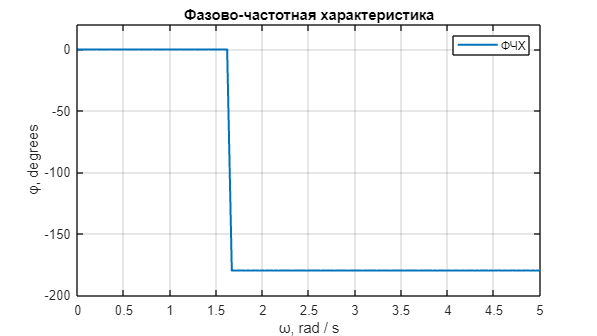


figure('Position', [1000 0 800 450])

plot(w, phi, 'LineWidth', 1.5,'DisplayName', 'ФЧХ')
title('Фазово-частотная характеристика')
legend()
ylabel('φ, degrees')
xlabel('ω, rad / s')
ylim([-200 20])
grid("on")



figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 15

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



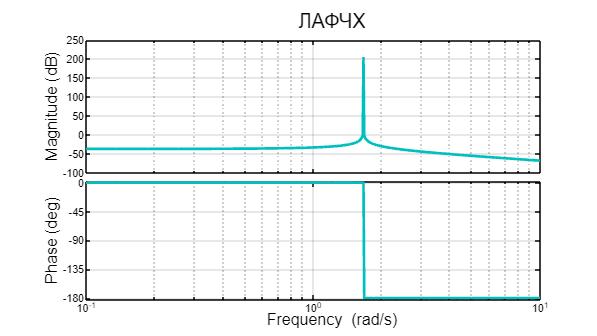

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2);